# Generation of Input, Lorenz-63 Simulation and Linearization Conditions

% % Setting parameters for the Lorenz-63 simulation

Fs = 16; % Sampling frequency
T  = 1/Fs; % Sampling period
ts = 30; % Time for spin up
tg = 4096; % Effective time for one trajectory
N  = (ts+tg)*Fs;
N1 = tg*Fs;
t  = T*(0:N-1);

% Parameters of the Lorenz-63 system
sigma = 10;
b = 8/3;
r = 28;

## Generation of the input series of sinusoidal forcing

% Setting the amplitudes of the forcing
Amp = zeros(3, Fs/2*tg);
% Set the amplitude at certain frequencies and use linear interpolation to
% set the values at remaining frequencies
node = [0.025,0.023,0.021,0.019,0.017,0.015,0.014,0.012,0.011,0.008,0.006,0.003;
        0.028,0.024,0.021,0.018,0.016,0.014,0.013,0.012,0.011,0.010,0.008,0.005;
        0.300,0.090,0.045,0.032,0.028,0.024,0.021,0.016,0.013,0.009,0.006,0.004]; % Amplitude at certain nodes
ind = round([0,0.01,0.02,0.1,1,2,3,4,5,6,7,8]*tg+1); % Frequencies of the nodes
% Linear interpolation procedure
for j = 1:(Fs/2*tg)
    k = find(j >= ind,1,"last");
    Amp(:,j) = (node(:,k)*(ind(k+1)-j) + node(:,k+1)*(j-ind(k)))/(ind(k+1)-ind(k));
end
Amp = [zeros(3,1), Amp];
Amp(3,2) = 0.60;

% Setting the random phases of the forcing
seed = 1; % Random seed
rng(seed,"twister"); % Random number generator
fai = rand(3,N1/2)*2*pi;
fai = [zeros(3,1), fai];

% Setting the forced frequencies, which are 16k+1 times of the bin frequency
fre = 1:16:N1/2;

% Generation of the input time series
f = sine_force(Amp,fai,fre);

## Parallel simulation

% % Simulation of the unforced system
ng_rest = 4096; % Number of trajectories, verified sufficient for the unforced case
rtol = 1e-5;
atol = 1e-8;
opt_rest = odeset(Reltol = rtol, AbsTol = atol);
seed = 0;
f_rest = zeros(3,N);

E_rest = NaN(3, N1/2 + 1, ng_rest); % Store the computing results of each trajectory
tic
% Open Parallel Computing Toolbox to speed up, please refer to your own computer 
% configuration determine the number of thread pools (default maximum to 8).
parpool('Processes', min(8, feature('numcores')));  
parfor k = 1:ng_rest % divide the total time into ng groups
    rng(seed*ng_rest + k,"twister")
    s0 = randn(3,1); % Initialization
    [~, s_rest] = ode45(@(t,s) lorenz(t,s,sigma,b,r,T,f_rest),t,s0,opt_rest); % Simulation
    s_rest = transpose(s_rest(Fs*ts+1:end,:)); % Discard the spinup
    S_rest = fft_single(s_rest); % Transform into frequency spectrum
    E_rest(:,:,k) = S_rest; % The k-th layer of E is the frequency domain data of the k-th tranjectory
end
delete(gcp('nocreate'));     % Close the Parallel Computing Toolbox
toc

历时 279.547962 秒。



S_rest_ba = mean(E_rest,3); % Signal when unforced
p_rest_ba = abs(S_rest_ba);  % Spectrum of the signal when unforced
p_rest_std = std(E_rest,[],3);

S0 = S_rest_ba(:,1);
S0(1:2) = 0;  % The steady-state of the unforced Lorenz-63 system (set <x>=<y>=0)

% % Simulation of the forced system
ng = 75000; % Number of trajectories
rtol = 1e-3;
atol = 1e-6;
opt  = odeset(Reltol=rtol, AbsTol=atol);

tic
parpool('Processes', min(8, feature('numcores')));  
s_sum = 0;
parfor k = 1:ng
    rng(seed*ng + k,"twister")
    s0 = randn(3,1); % Initialization
    [~, s] = ode45(@(t,s) lorenz(t,s,sigma,b,r,T,f),t,s0,opt);
    s = transpose(s(Fs*ts+1:end,:)); % Discard the spinup
    s_sum = s_sum + s;
end
delete(gcp('nocreate'));     % Close the Parallel Computing Toolbox
toc

s_ba = s_sum / ng; % Time domian signal under the sinusoidal forcing
S_ba = fft_single(s_ba);
p_ba = abs(S_ba);
noise = p_rest_std/sqrt(ng); % Noise under the sinusoidal forcing

## Visualization of the linearization conditions

% Create file firectroy "figures" to place produced figures 
mkdir("figures");

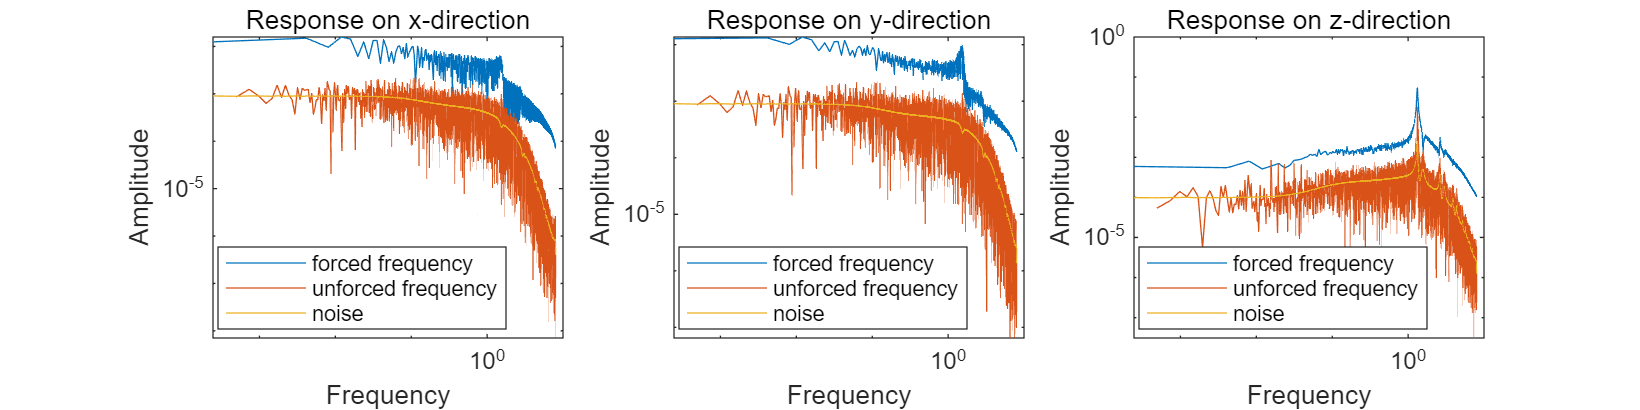

filedir = [pwd '\figures'];

figure;
scnsize  = get(0,'ScreenSize'); 
len = 1200;
wid = 300;
set(gcf,'Position', [scnsize(1,3)/2-len/2, scnsize(1,4)/2-wid/2,len, wid]);

subplot(1,3,1);
loglog(Fs/N1*fre,p_ba(1,fre+1),Fs/N1*un_fre,p_ba(1,un_fre+1),Fs/N1*(0:N1/2),p_rest_std(1,:)/sqrt(ng))
legend("forced frequency","unforced frequency","noise", 'location', 'best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Response on x-direction");

subplot(1,3,2);
loglog(Fs/N1*fre,p_ba(2,fre+1),Fs/N1*un_fre,p_ba(2,un_fre+1),Fs/N1*(0:N1/2),p_rest_std(2,:)/sqrt(ng))
legend("forced frequency","unforced frequency","noise", 'location', 'best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Response on y-direction");

subplot(1,3,3);
loglog(Fs/N1*fre,p_ba(3,fre+1),Fs/N1*un_fre,p_ba(3,un_fre+1),Fs/N1*(0:N1/2),p_rest_std(3,:)/sqrt(ng))
legend("forced frequency","unforced frequency","noise", 'location', 'best')
xlabel("Frequency")
ylabel("Amplitude")
xlim([0 10])
title("Response on z-direction")

exportgraphics(gcf, [filedir '\linearization_conditions.pdf'], 'ContentType', 'vector', 'BackgroundColor', 'none');

% % Storage of the input and output data
u = f(:,Fs*ts+1:end); % Input data
y = s_ba-S0; % Output data: difference between signals with and without forcing
dat = iddata(y',u',T);
% Considering the symmetries of the Lorenz-63 system
u_inv = [-u(1,:);-u(2,:);u(3,:)];
y_inv = [-y(1,:);-y(2,:);y(3,:)];
dat_inv = iddata(y_inv',u_inv',T);
dat_mer = merge(dat, dat_inv);